# Programación

## Proposiciones lógicas

p=1>0

p = logical
   1


q=1<0

q = logical
   0


a=2

a = 2

a==3

ans = logical
   0


p1=1>3; %F
p2=2<5; %V
p1&&p2 %F

ans = logical
   0


p1||p2 %V

ans = logical
   1


p1&p2 %F

ans = logical
   0


p1|p2 %V

ans = logical
   1


A=[1 2 3;0 -1 4;3 9 8];
B=[1 -1 0; 4 2 -3;0 0 9];
A>B

ans = 3×3 logical array
   0   1   1
   0   0   1
   1   1   0


A<B

ans = 3×3 logical array
   0   0   0
   1   1   0
   0   0   1


A==B

ans = 3×3 logical array
   1   0   0
   0   0   0
   0   0   0


x=[0 -1 4 2];
any(x) % Detecta elementos ~=0

ans = logical
   1


x=zeros(1,4)

x =      0     0     0     0


any(x)

ans = logical
   0


A=[0 4 1;0 0 -1;0 0 2];
any(A)

ans = 1×3 logical array
   0   1   1


x=[1 2 2 3];
all(x)

ans = logical
   1


x=0:3;
all(x)

ans = logical
   0


A=[0 4 1;0 0 -1;0 0 2]

A =      0     4     1
     0     0    -1
     0     0     2


any(A)

ans = 1×3 logical array
   0   1   1


all(A)

ans = 1×3 logical array
   0   0   1


# Comandos if

x=rand;
if x<0.5
    disp(x)
    disp('hola')
end

    0.4854



hola


a=10;
b=30;
t=rand

t = 0.8003

x=a+t*(b-a);
disp(x)

   26.0056



rand(2,3)

ans =     0.1419    0.9157    0.9595
    0.4218    0.7922    0.6557


Describe si un número es primo

numero=1997

numero = 1997

x=rem(numero,2:numero-1)

x =      1     2     1     2     5     2     5     8     7     6     5     8     9     2    13     8    17     2    17     2    17    19     5    22    21    26     9    25    17    13    13    17    25     2    17    36    21     8    37    29    23    19    17    17    19    23    29    37    47     8


if all(x)==0
    disp('no es primo')
else
    disp('es primo')
end

es primo


Hay dos raices reales distintas


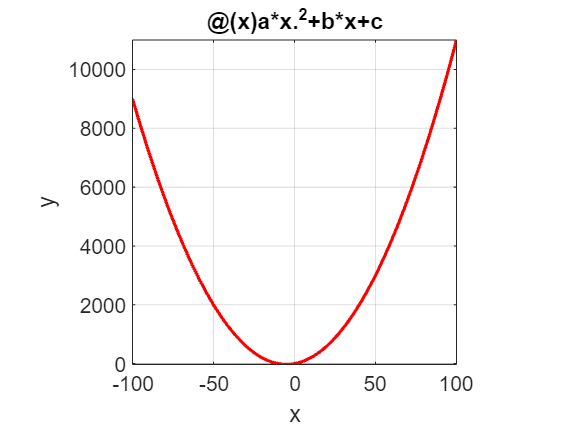

x1 = 0.0990

x2 = -10.0990

[x1,x2]=cuad(1,10,-1,-100,100)

El punto (0  0) está en el origen


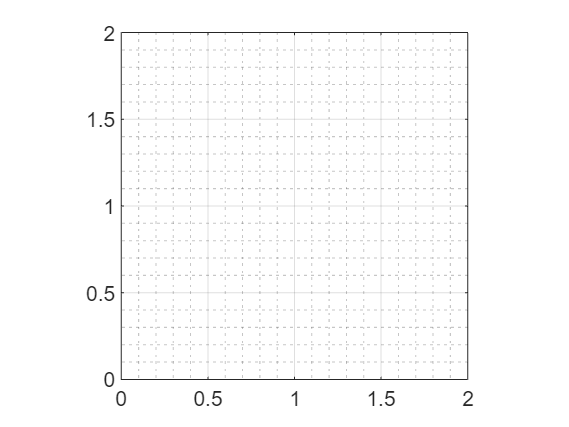


cuadrante(0,0)

El punto (1  1) está en el cuadrante 1


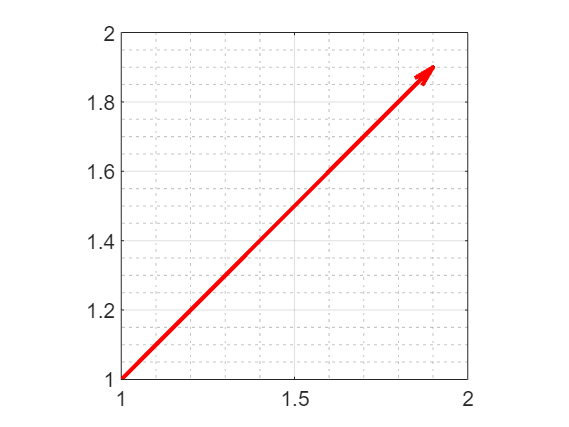

cuadrante(1,1)

El punto (-1 -1) está en el cuadrante 3


cuadrante(-1,-1)

El punto (-1  1) está en el cuadrante 2


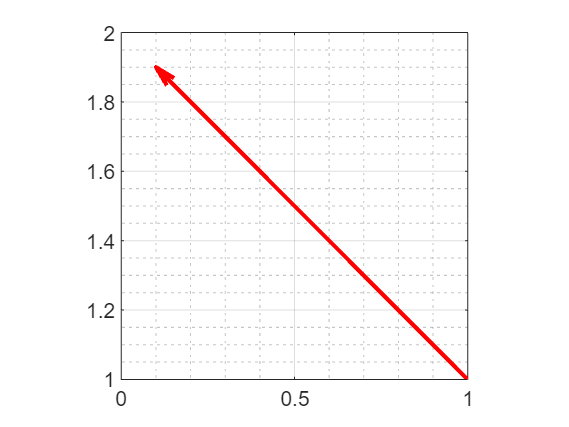

cuadrante(-1,1)

El punto (1 -1) está en el cuadrante 4


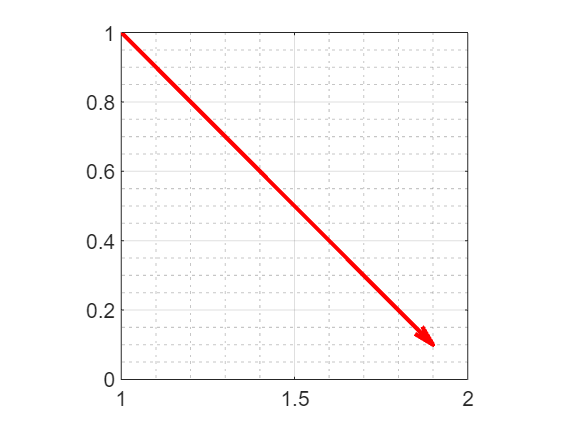

cuadrante(1,-1)

El punto (1  0) está en el eje x


cuadrante(1,0)

El punto (0  1) está en el eje y


cuadrante(0,1)

# Ciclos

## For

% x=10;
% for k=1:5
% x=x+1;
% disp(x)
% end

tic 
v=nnumerosprimos2(6000); 
toc

Elapsed time is 0.591421 seconds.


tic 
v=nnumerosprimos(6000); 
toc

Elapsed time is 0.581697 seconds.


## Ciclo while

while proposición

    comandos

end

tic
v=nnumerosprimos3(375)

v =      2
     3
     5
     7
    11
    13
    17
    19
    23
    29


toc

Elapsed time is 1.129401 seconds.


# Switch

d=input('Numero del dia: ')

d = 4

switch d
    case 1, disp('Lunes')
    case 2, disp('Martes') 
    case 3, disp('Miércoles') 
    case 4, disp('Jueves') 
    case 5, disp('Viernes') 
end

Jueves


Ejemplo: simulación del lanzamiento de un dado n veces

format long
f=simulacion_dado(100000000)
1/6